%[Bz,Az]=mi_fir1(N, Wn*2, TIPO_FILTRO, TIPO_VENTANA);

function [B,A]=mi_fir1(varargin)

% N, W, VENTANA
% number of arguments check
narginchk(2,4);
N=double(varargin{1});
Wc=double(varargin{2});
TIPO="paso bajo"; 
if nargin>=3
    TIPO=varargin{3};
end
VENTANA="rectangular";
if nargin>=4
    VENTANA=varargin{4};
end

            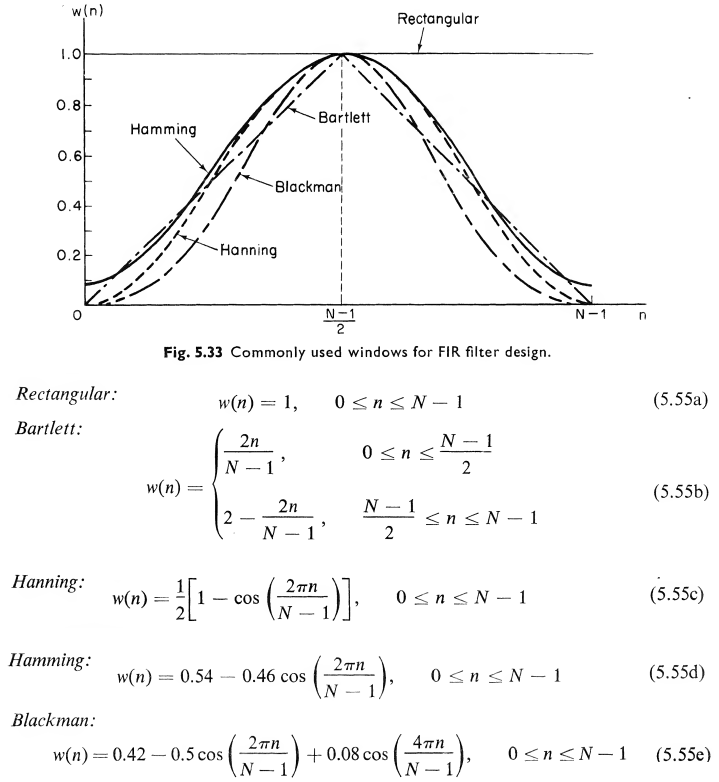

    %selección de la ventana
    w = @(m) 1;
    switch VENTANA
        case "rectangular"
            w = @(m) 1;
        case "hanning"
            w = @(m) 1/2*[1-cos(2*pi*m/(N-1))];
        case "hamming"
            w = @(m) 0.54 - 0.46*cos(2*pi*m/(N-1));
        case "blackman"
            w = @(m) 0.42 - 0.5*cos(2*pi*m/(N-1))- 0.08*cos(4*pi*m/(N-1));            
    end

[dietrich]       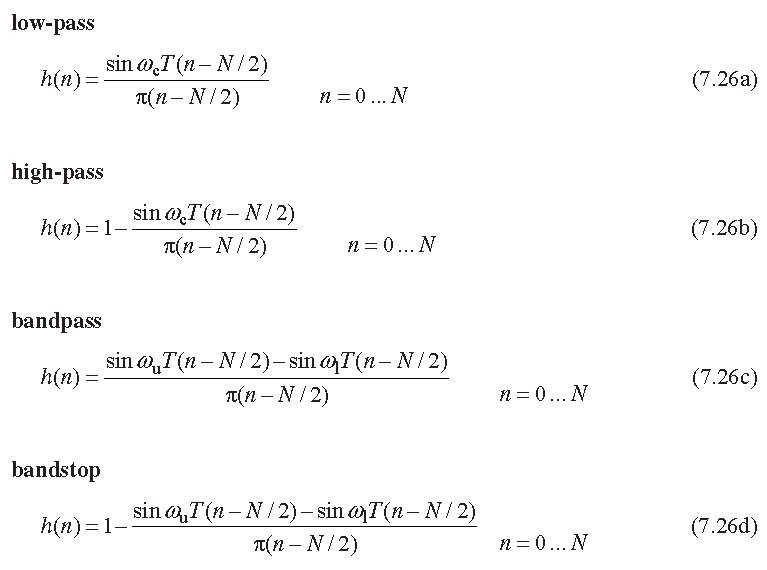

    hd0 = Wc(end);
    switch TIPO
        case "pasa_alto"
            Wc=2-Wc(end); 
            hd0=1-hd0; 
    end 

    syms n ;
    m =(N-1)/2 ;
    h = @(n) sin(Wc(end)*pi*(n - m ))./(pi*(n-m));

    if ( mod (N ,2) ==1)
        B=[ h(0:(N-3)/2) hd0 h((N+1)/2:(N-1))].*w(0:N-1);
    else
        B=[ h(0:N-1) ].*w(0:N-1);
    end
    A=1;

end